# TCLab Impulse Response

**Objective**: Compare an analytic solution of a FOPDT model with an impulse response of the TCLab.

1) Perform a two minute impulse test with heater 1 to 70% starting at 10 seconds for 1 minute (between 10 and 70 seconds) and continue until 120 seconds.

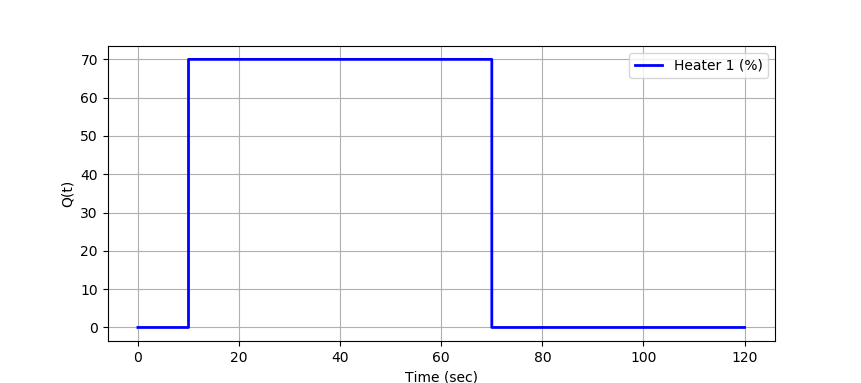

2) Create a plot of the temperature response over 2 minutes that shows the heater level (%), measured temperature ($^\circ \text{C}$), and predicted temperature ($^\circ \text{C}$). Instead of using an ODE solver, derive an analytical solution and simulate a [**first order plus dead time (FOPDT) model**](https://apmonitor.com/pdc/index.php/Main/FirstOrderSystems). The FOPDT model is:


$$\tau_p \frac{dT'}{dt} = -T' + K_p \, Q'\left(t-\theta_p\right)$$


where $T'=T-T_{ss}$ and $Q'=Q-Q_{ss}$ are deviation variables with steady-state initial conditions $T_{ss} = T_{Ambient}$ and $Q_{ss}=0\%$. Use the following script to generate a plot (*Impulse_Response.png*) and data file (*Impulse_Response.csv*).

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);

% Collect data
filename = "Impulse_Response.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path);
    tm_ = A(:,1);
    Q1_ = A(:,2);
    T1_ = A(:,3);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        n = 120;
        tm_ = zeros(n, 1);
        T1_ = zeros(n, 1);
        Q1_ = zeros(n, 1);
        Q1_(11:72) = 70.0;
        % initialize lab
        lab = tclab;
        tic;
        for i=1:n
            tm_(i) = toc;
            T1_(i) = lab.T1;
            lab.Q1(Q1_(i));
            f = figure(1);
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.')
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r.')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            pause(mod(1-toc,1));
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm_ Q1_, T1_]
        writematrix(A, absolute_path, 'Delimiter', ',')
        f = gcf;
        
        % Requires R2020a or later
        exportgraphics(f,'Impulse_Response.png','Resolution',300)
                
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

Apply a laplace Transform to the FOPDT equation and  derive an analytic solution for $T(t)$. Then graph the analytic solution and  the TCLab Steptest to compate results. The analytic solution is included below.

[SOLUTION VIDEO]

Apply the [**Laplace transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) to each of the terms in the FOPDT equation. Because the Laplace transform is a linear operator, each term can be transformed separately. Because $T'(t)$ is a deviation variable, the initial condition at the initial time is $T'(0)=0$.


$$\mathcal{L}\left(\tau_p \frac{dT'(t)}{dt}\right) = \tau_p \left(s \, T(s) - T'(0)\right) = \tau_p s \, T(s)$$



$$\mathcal{L}\left(-T'(t)\right) = -T(s)$$



$$\mathcal{L}\left(K_p \, Q'(t-\theta_p)\right) = K \, Q(s) \, e^{-\theta_p s}$$


Putting these terms together gives the first-order differential equation in the Laplace domain.


$$\tau_p \, s \, T(s) = -T(s) + K_p \, Q(s) \, e^{-\theta_p s}$$


The *T(s)* terms are collected to the left side of the equation.


$$T(s) = \frac{K_p}{\tau_p s + 1} e^{-\theta_p s} Q(s)$$


The differential equation as a function of time (*t*) is now an algebraic equation in the Laplace domain (*s*). The input function is:


$$Q(s) = \frac{70}{s} \, e^{-10 s} - \frac{70}{s} \, e^{-70 s}$$


This gives an expression for *T(s)* in Laplace form.


$$T(s) = \frac{K_p}{\tau_p s + 1} e^{-\theta_p s} \left(\frac{70}{s} \, e^{-10 s} - \frac{70}{s} \, e^{-70 s}\right)$$


With $\theta_p = 15$ sec, an [**inverse Laplace transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) gives the analytic solution for $T(t)$.


$$T(t) = 70 \, K_p \, \left(1-e^{-\frac{t-25}{\tau_p}}\right) S(t-25) - 70 \, K_p \, \left(1-e^{-\frac{t-85}{\tau_p}}\right) S(t-85)$$


viewSolution(false)

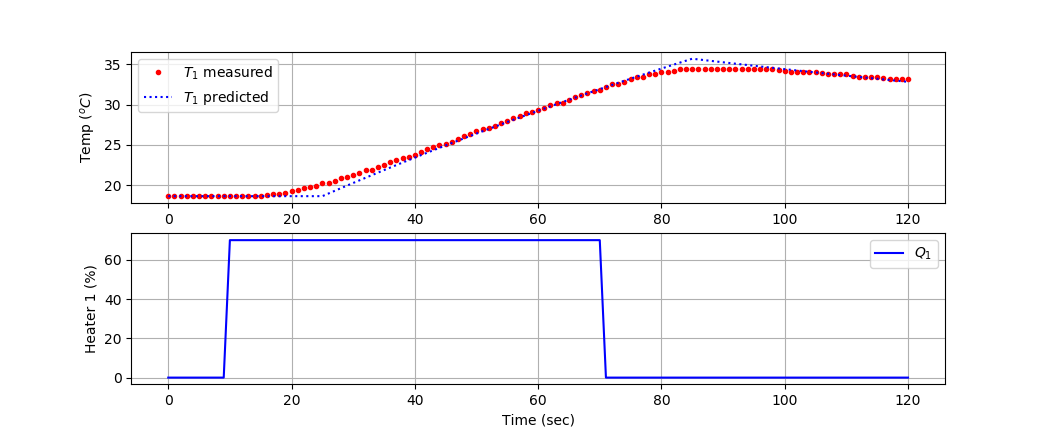

A = readmatrix(absolute_path);
tm_ = A(:,1);
Q1_ = A(:,2);
T1_ = A(:,3);
disp('TCLab Data read from file')

n = length(tm_);
Kp = 0.9;
taup = 190.0;

% Step Functions
s1 = zeros(n, 1);
s1(25:end) = 1.0;
s2 = zeros(n, 1);
s2(85:end) = 1.0;

% Analytic Solution
T1s = 0;

% Create Figure
f = figure(2);
subplot(2,1,1)
plot(tm_,T1_,'r.','DisplayName','$T_1$ measured')
hold on
plot(tm_,T1s,'b:','DisplayName','$T_1$ predicted')
hold off
ylabel('Temp ($^oC$)')
legend("Location","best","Interpreter","latex")
subplot(2,1,2)
plot(tm_,Q1_,'b-','DisplayName','$Q_1$')
ylabel('Heater 1 (%)')
xlabel('Time (sec)')
legend("Location","best","Interpreter","latex")
exportgraphics(f, 'Impulse_Response.png','Resolution',300)


function viewSolution(view)
if view
    disp('70 * Kp * (1.0-exp(-(tm_-25.0)/taup)).*s1 - ...' + newline ...
      + '70 * Kp * (1.0-exp(-(tm_-85.0)/taup)).*s2 + T1_(1)')
end
end